# ESERCITAZIONE___ESAME_06/07/2026___SALVATORE_RAIOLA_DE600000

clear; close all; clc;

## DEFINIZIONI

#### Variabili Simboliche 

syms x1 x2 x3 x4 dx1 dx2 dx3 dx4 u1 u2 real

#### Ingresso-Stato-Uscita

% Ingresso
u = [u1;
     u2];

% Stato
x = [x1;
     x2;
     x3;
     x4];

% Uscita
y = [x1;
     x3];

n = size(x,1);
m = size(u,1);
p = size(y,1);

#### Modello Dinamico Non Lineare

eq_1_sym = dx1 == x2;
eq_2_sym = dx2 == -0.8*sin(x1) -0.5*x2 +0.3*x4 +u1;
eq_3_sym = dx3 == x4;
eq_4_sym = dx4 == -0.6*sin(x3) -0.4*x4 + 0.2*x2 +u2 +0.1*cos(x1);

eqs_sym = [eq_1_sym;
           eq_2_sym;
           eq_3_sym;
           eq_4_sym];

model = solve(eqs_sym, [dx1, dx2, dx3, dx4], "ReturnConditions", true);

% dx/dt
f = [model.dx1;
     model.dx2;
     model.dx3;
     model.dx4];

% y
g = y;

#### Punto di Equilibrio

x_bar = zeros(4,1);
u_bar = [0;
         -0.1];

## LINEARIZZAZIONE

#### Verifica Punto di equilibrio

eqs_peql = subs(eqs_sym, [x; u], [x_bar; u_bar]);

peql = solve(eqs_peql, [dx1, dx2, dx3, dx4], "ReturnConditions", true);

dx_peql = [peql.dx1; peql.dx2; peql.dx3; peql.dx4];

if all(double(dx_peql) == 0)
    disp('Il punto (x_bar, u_bar) è un punto di equilibrio');
else
    disp('Il punto (x_bar, u_bar) NON è un punto di equilibrio');
end

Il punto (x_bar, u_bar) è un punto di equilibrio


#### Linearizzazione attorno a (x_bar, u_bar)

A_sym = jacobian(f,x);
B_sym = jacobian(f,u);
C_sym = jacobian(g,x);
D_sym = jacobian(g,u);

A = double(subs(A_sym, [x; u], [x_bar; u_bar]));
B = double(subs(B_sym, [x; u], [x_bar; u_bar]));
C = double(subs(C_sym, [x; u], [x_bar; u_bar]));
D = double(subs(D_sym, [x; u], [x_bar; u_bar]));

sys = ss(A, B, C, D)


sys =
 
  A = 
         x1    x2    x3    x4
   x1     0     1     0     0
   x2  -0.8  -0.5     0   0.3
   x3     0     0     0     1
   x4     0   0.2  -0.6  -0.4
 
  B = 
       u1  u2
   x1   0   0
   x2   1   0
   x3   0   0
   x4   0   1
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


#### Verifica Controllabilità

if rank(ctrb(A,B)) == n
    disp('IL sistema è completammente controllabile');
else
    disp('IL sistema NON è completammente controllabile');
end

IL sistema è completammente controllabile


#### Verifica Osservabilità

if rank(obsv(A,C)) == n
    disp('IL sistema è completammente osservabile');
else
    disp('IL sistema NON è completammente osservabile');
end

IL sistema è completammente osservabile


## ASSEGNAMENTO AUTOVALORI CON METODO DI SYLVESTER

#### Specifiche

eig_des = [-2, -2.5, -3, -4];

x0_eig = [0.1;
          0;
          -0.1;
          0];

#### Sintesi con metodo di Sylvester

Lambda = diag(eig_des);
G = rand(m,n);

X = sylvester(A, -Lambda, -B*G);

K_eig = -G/X

K_eig =    -2.0498    2.1175    8.3548    3.0752
   -9.8380   -2.9498   17.1584    8.4825



A_cl_eig = A-B*K_eig;
eig(A_cl_eig)

ans =    -4.0000
   -2.0000
   -2.5000
   -3.0000


#### Verifica Performance Sistema Linearizzato

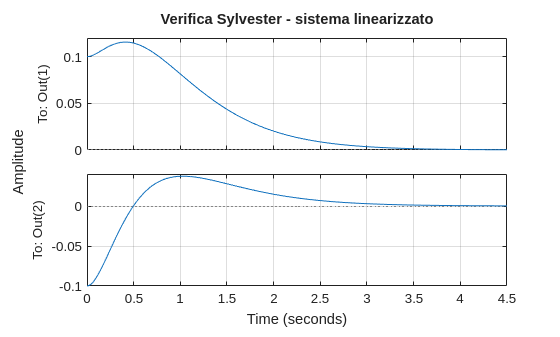

sys_eig = ss(A_cl_eig, B, C, D);

figure;
initial(sys_eig, x0_eig);
grid on
title('Verifica Sylvester - sistema linearizzato');

#### Verifica Performance Sistema Non Lineare

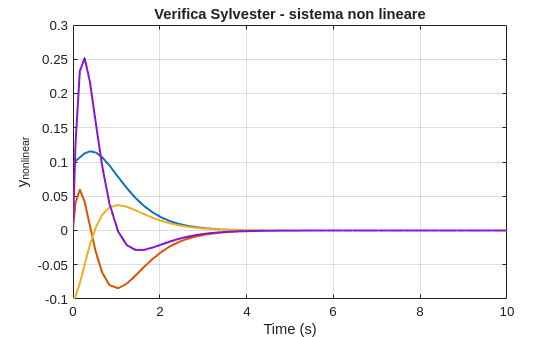

out = sim('Verifica_EIG_06072026.slx');

y1_nonlinear = squeeze(out.y1_nonlinear.Data);
y2_nonlinear = squeeze(out.y2_nonlinear.Data);
y3_nonlinear = squeeze(out.y3_nonlinear.Data);
y4_nonlinear = squeeze(out.y4_nonlinear.Data);
time = squeeze(out.y1_nonlinear.Time);

% Plot 
figure;
plot(time, y1_nonlinear, "LineWidth", 1.5);
hold on
plot(time, y2_nonlinear, "LineWidth", 1.5);
hold on
plot(time, y3_nonlinear, "LineWidth", 1.5);
hold on
plot(time, y4_nonlinear, "LineWidth", 1.5);
xlabel('Time (s)');
ylabel('y_{nonlinear}');
title('Verifica Sylvester - sistema non lineare');
grid on

#### Schema simulink completo consultabile in:

#### [Verifica_Sylvester](matlab:open_system('Verifica_EIG_nonlinear.slx'))

## CONTROLLO LQR CON AZIONE INTEGRATIVA

#### Specifiche

% Tempo di Assestamento
Ts = 0.9;
alpha = 4/Ts;

% Riferimento
r = [0.2;
     -0.1];

z = 2;

n_tilde = n+z;

#### Sistema Aumentato

C_LQR = [1, 0, 0, 0;
         0, 0, 1, 0];

A_aum = [A, zeros(n,z);
         -C_LQR, zeros(z,z)];

A_hat = A_aum + alpha*eye(n_tilde);

B_aum = [B;
         zeros(z,m)];

C_aum = [C zeros(p,z)];

D_aum = zeros(p,m);

sys_aum = ss(A_hat, B_aum, C_aum, D_aum)


sys_aum =
 
  A = 
          x1     x2     x3     x4     x5     x6
   x1  4.444      1      0      0      0      0
   x2   -0.8  3.944      0    0.3      0      0
   x3      0      0  4.444      1      0      0
   x4      0    0.2   -0.6  4.044      0      0
   x5     -1      0      0      0  4.444      0
   x6      0      0     -1      0      0  4.444
 
  B = 
       u1  u2
   x1   0   0
   x2   1   0
   x3   0   0
   x4   0   1
   x5   0   0
   x6   0   0
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   0   1   0   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


#### Sintesi LQR

Q_bar = 1;
Q = C_aum'*Q_bar*C_aum + blkdiag(zeros(n,n), 20*eye(z))

Q =      1     0     0     0     0     0
     0     0     0     0     0     0
     0     0     1     0     0     0
     0     0     0     0     0     0
     0     0     0     0    20     0
     0     0     0     0     0    20


R = eye(m)

R =      1     0
     0     1



K_LQR = lqr(sys_aum, Q, R)

K_LQR =   228.1664   25.6664    3.5345    0.4985 -670.1517  -15.7359
    5.3007    0.4985  230.1557   25.8784  -23.5349 -677.2091



K_LQR_x = K_LQR(:, 1:n);
K_LQR_i = K_LQR(:, n+1:end);

#### Verifica Simulazione

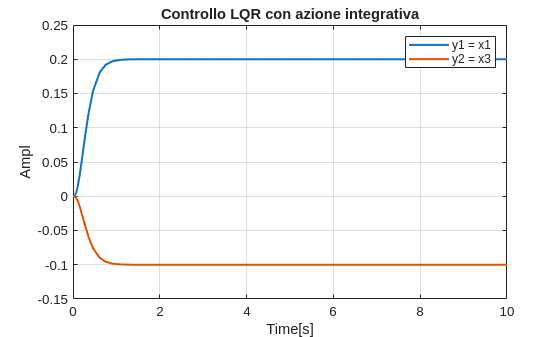

% Plot MATLAB
out = sim('Verifica_LQR_06072026.slx');
y_lqr = out.y.Data;
time = out.y.Time;

figure
plot(time, y_lqr, "LineWidth", 1.5);
grid on
xlabel("Time[s]");
ylabel("Ampl");
legend('y1 = x1', 'y2 = x3');
title('Controllo LQR con azione integrativa')